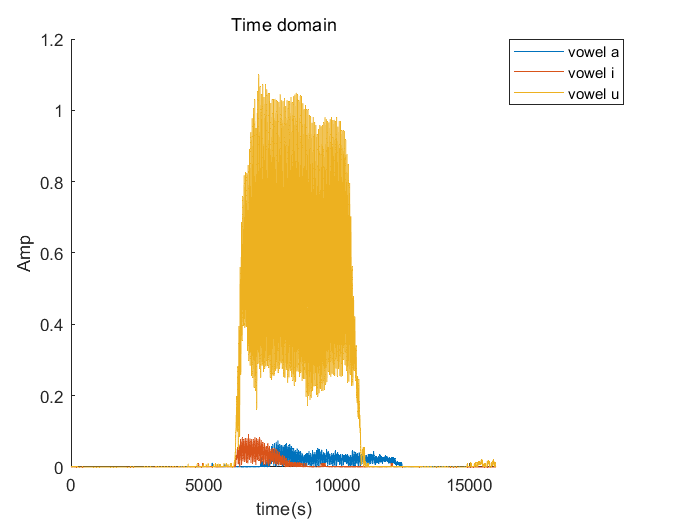

fs = 8000 ; 
nBits = 16 ; 
nChannels = 1 ; 
ID = -1; % default audio input device 
time = 2;
N = 3;


% 读取音频
[y, y_up, y_down, Y, Y_up, Y_down, mag, mag_up, mag_down] = deal(zeros(fs*time, N));

for i = 1:N
    str = i+".wav";
    [y(:,i), ~] = audioread(str);
    [y_up(:, i), y_down(:,i)] = envelope(y(:,i));
    
    Y(:,i) = (fft(y(:,i)));
    Y_up(:,i) = (fft(y_up(:,i)));
    Y_down(:,i) = (fft(y_down(:,i)));

    mag(:,i) = 20 * log10(abs(Y(:,i)));
    mag_up(:,i) = 20 * log10(abs(Y_up(:,i)));
    mag_down(:,i) = 20 * log10(abs(Y_down(:,i)));
end


vowel = ['a', 'i', 'u'];
str = "";
% 时域图
figure, hold on
for i = 1:N
%     plot(y(:,i));
    plot(y_up(:,i));
%     plot(y_down(:,i));
    str(i) = "vowel "+vowel(i);
end
hold off
xlabel("time(s)"), ylabel("Amp"), title("Time domain"), legend(str, 'Location','bestoutside');

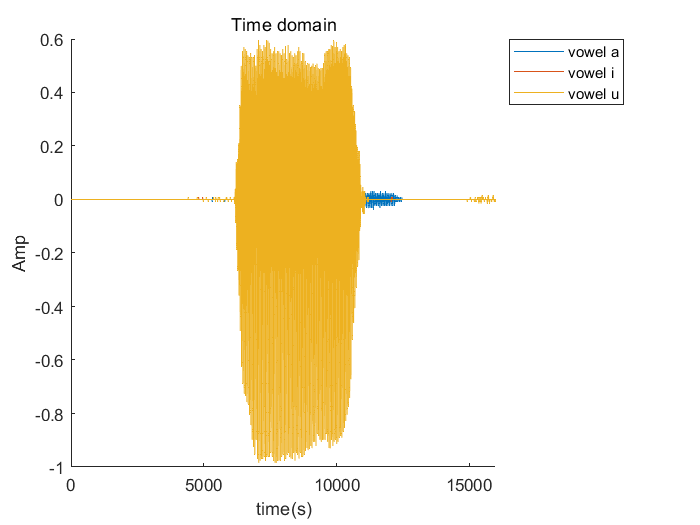

% 时域图2
figure, hold on
for i = 1:N
    plot(y(:,i));
%     plot(y_up(:,i));
%     plot(y_down(:,i));
    str(i) = "vowel "+vowel(i);
end
hold off
xlabel("time(s)"), ylabel("Amp"), title("Time domain"), legend(str, 'Location','bestoutside');

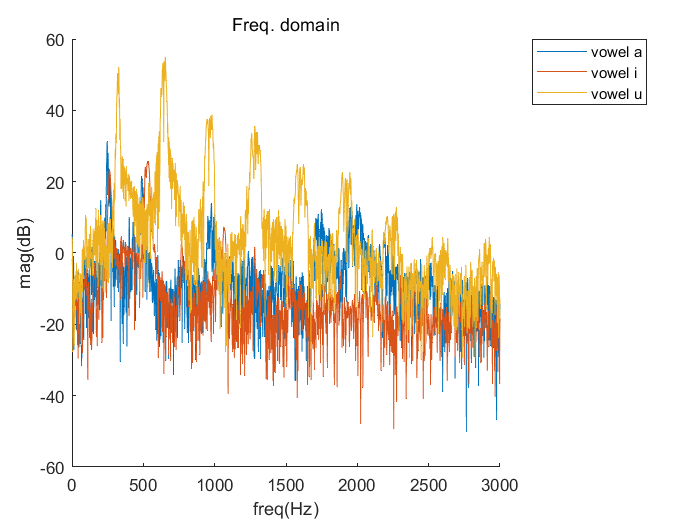

% 频域图
figure, hold on
for i = 1:N
%     plot(f, mag(:,i));
%     plot(f, mag_down(:,i));
    plot(mag(1:3e3,i));
    str(i) = "vowel "+vowel(i);
end
hold off
xlabel("freq(Hz)"), ylabel("mag(dB)"), title("Freq. domain"), legend(str, 'Location', 'bestoutside');    

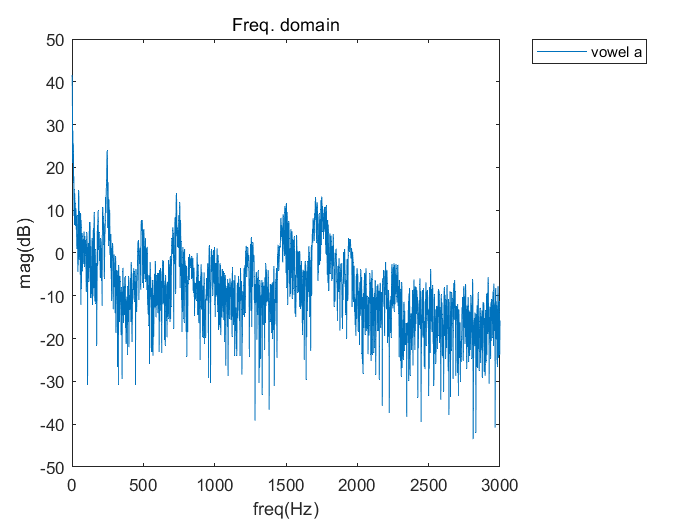

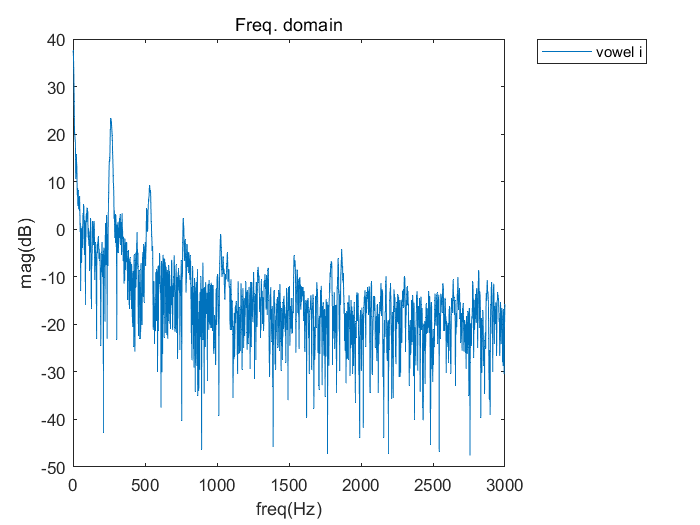

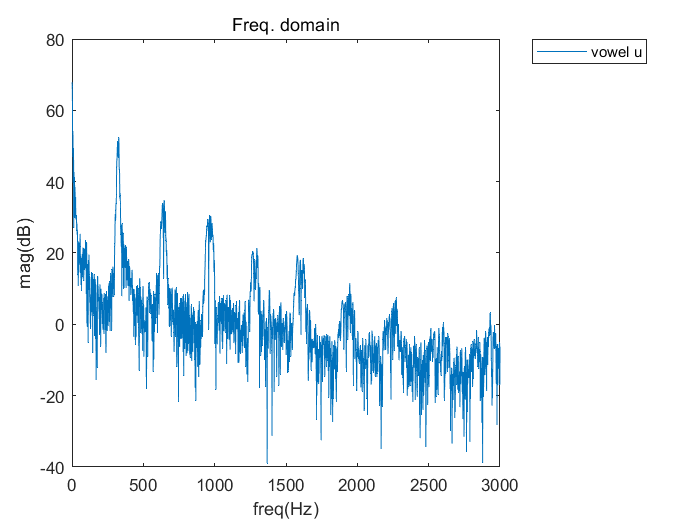


% subplot
for i = 1:N
    str = "vowel "+vowel(i);
    figure, plot(mag_up(1:3e3,i)),...
        xlabel("freq(Hz)"), ylabel("mag(dB)"),...
        title("Freq. domain"), legend(str, 'Location', 'bestoutside');    
end

% 获得谐波幅度和频率
harmonic_freq = [
    300, 602, 905, 1210, 1512; 
    332, 653, 978, 1295, 1629; 
    311, 608, 951, 1245, 1565];
harmonic_mag = [
    57.7015, 55.2682, 54.4646, 50.3639, 43.722; 
    56.8667, 46.813, 39.9905, 48.7406, 38.2547; 
    57.7557, 44.453, 38.123, 34.886, 29.3539];
% 合成复合音
harmonic_mag = 10.^(harmonic_mag / 20);
t = 0:(1/(fs-1)):1;
[y_syn, Y_syn, mag_syn] = deal(zeros(fs, N));
for i = 1:N
    tone = sin(2 * pi * t' * harmonic_freq(i,:));
    tone = tone .* harmonic_mag(i,:) / max(harmonic_mag(:,i));
    y_syn(:,i) = sum(tone,2);
%     归一化
    y_syn(:,i) = y_syn(:,i) / max(y_syn(:,i));
%     FFT
    Y_syn(:,i) = (fft(y_syn(:,i)));
    mag_syn(:,i) = 20 * log10(abs(Y_syn(:,i)));

    audiowrite(("syn_"+i+".wav"), y_syn(:,i), fs)
end

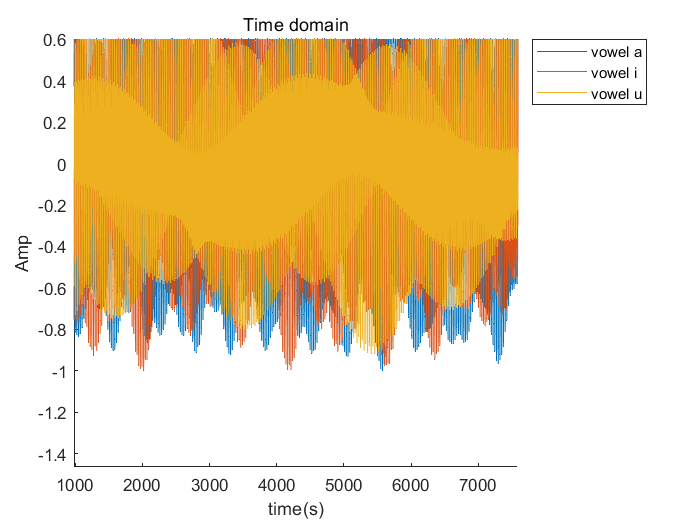



str = "";
% 时域图
figure, hold on
for i = N:-1:1
%     plot(y(:,i));
    plot(y_syn(:,i));
    str(i) = "vowel "+vowel(i);
end
hold off
xlabel("time(s)"), ylabel("Amp"), title("Time domain"), legend(str, 'Location', 'bestoutside');

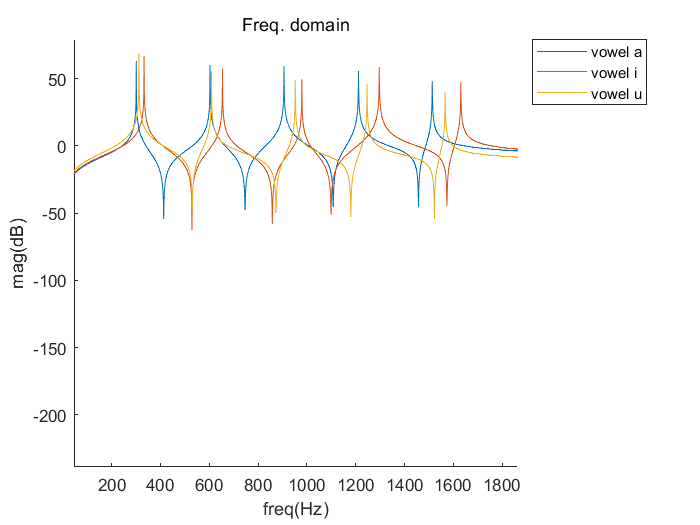


% 频域图
figure, hold on
for i = 1:N
%     plot(mag(:,i));
    plot(mag_syn(1:2e3,i));
    str(i) = "vowel "+vowel(i);
end
hold off
xlabel("freq(Hz)"), ylabel("mag(dB)"), title("Freq. domain"), legend(str, 'Location', 'bestoutside');    

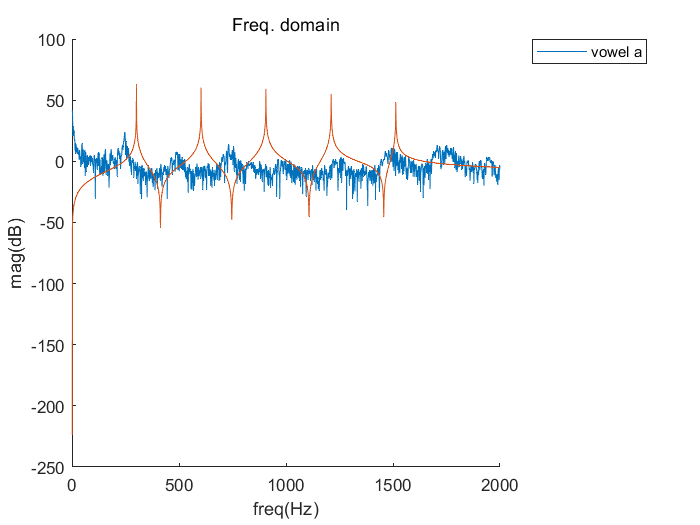

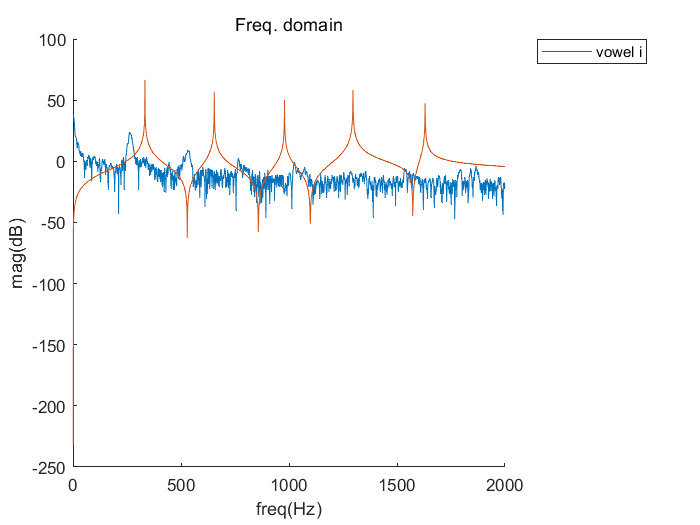

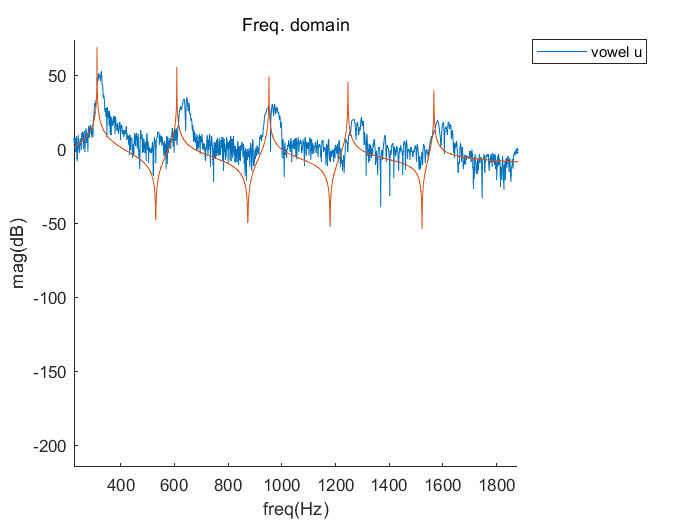


% subplot
for i = 1:N
    str = "vowel "+vowel(i);
    
    figure, hold on, plot(mag_up(1:2e3,i)), plot(mag_syn(1:2e3,i)),...
        xlabel("freq(Hz)"), ylabel("mag(dB)"),...
        title("Freq. domain"), legend(str, 'Location', 'bestoutside');
end